Ts = 1;
N = 1000;
Es = 1;
m = zeros(1,N);
M = 4;
Fs = 20;
Fc = 6;
t_total = Ts*N;




for i = 1:N
    m(i) = sqrt(Es)*exp(1j*2*pi*randi(4, 1)/M);
end
%scatterplot(m)


m_up = upsample(m, Fs);
cosfir = rcosfir(0, Ts*N, 10, Ts)

cosfir =    -0.0000   -0.0984   -0.1871   -0.2576   -0.3029   -0.3185   -0.3029   -0.2577   -0.1872   -0.0985    0.0000    0.0985    0.1873    0.2579    0.3032    0.3188    0.3032    0.2580    0.1874    0.0986   -0.0000   -0.0986   -0.1875   -0.2581   -0.3035   -0.3191   -0.3035   -0.2582   -0.1876   -0.0986   -0.0000    0.0987    0.1877    0.2584    0.3038    0.3194    0.3038    0.2585    0.1878    0.0987   -0.0000   -0.0988   -0.1879   -0.2586   -0.3041   -0.3197   -0.3041   -0.2587   -0.1880   -0.0988


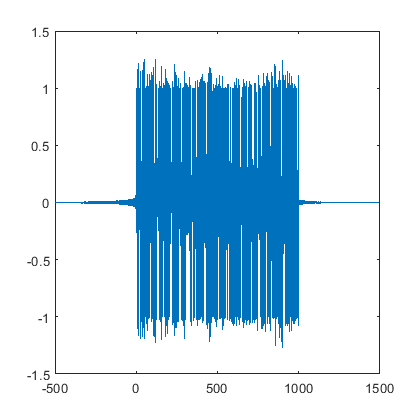

c = conv(m_up, cosfir);
s = real(c);

t = linspace(-(t_total/2-1), t_total+(t_total/2-1), length(c));
f = linspace(-Fs/2,Fs/2,length(c));

S = fftshift(fft(s));
plot(t, s);

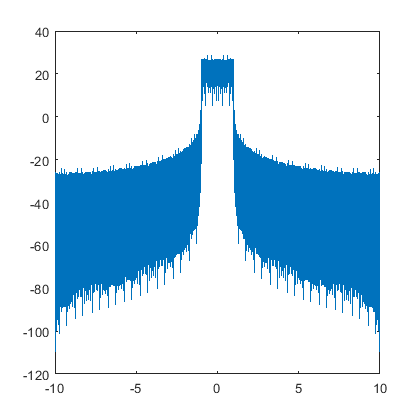

plot(f,10*log10(abs(S)));